titles = {'CS-on','Reward','Intertrial Interval'};
title_options.Rotations = [90, 90, 0];

durations = [seconds(8), seconds(1), seconds(60)];
% colors = [0.0, 0.5, 0.0
%                0.2, 1.0, 0.2
%                0.0, 0.2, 0.0];
colors = [0.0, 0.5, 0.0
               0.9, 0.1, 0.1
               0.0, 0.2, 0.0];
%% Add the state_map:
plottingOptions.orientation = 'horizontal';
plottingOptions.plot_variable = 'behavioral_state';
plottingOptions.vertical_state_mode = 'combined';
plottingOptions.x_axis = 'timestamp'; % Timestamp-appropriate relative bins

figure(1);
% [stateMapHandle] = fnPlotStateDiagram(active_processing, state_statemapPlottingOptions);



## Build Time Plot

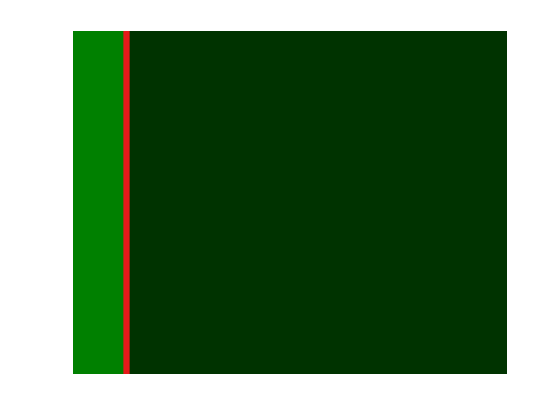

clf;
totalDuration = sum(durations, 'all');
proportionalDurations = durations ./ totalDuration;

numBlocks = length(proportionalDurations);

% Cumulative sum start timesteps
end_timesteps = cumsum(durations);
start_timesteps = end_timesteps - durations;
        
state_y_offsets = ones([numBlocks 1]) - 0.5;
states = [seconds(start_timesteps)', ...
    seconds(end_timesteps)'];

   
t = 0:1:seconds(totalDuration);

for s_idx = 1:numBlocks

%     curr_s_y = 1.0-0.5;
    curr_s_y = state_y_offsets(s_idx);
    
    % 
    if strcmpi(plottingOptions.orientation, 'vertical')
        % If vertically oriented, flip the x and y values
        temp.rect_pos = [curr_s_y, states(s_idx,1), 1, diff(states(s_idx,1:2))];
    else
        temp.rect_pos = [states(s_idx,1), curr_s_y, diff(states(s_idx,1:2)), 1];
    end
    
    rectangle('Position', temp.rect_pos,...
                'LineStyle','none','facecolor', colors(s_idx,:))
end
    

% Cleanup
ax = gca;
% combined mode:
state_stack_dim.Tick = [];
state_stack_dim.TickLabel = '';
state_stack_dim.Lim = 0.5 + [0,1];
% state_stack_dim.Lim = [0,1];
state_stack_dim.Dir='reverse';

length_dim.Lim = t([1,end]);
length_dim.Axis.Visible = 'off';

if strcmpi(plottingOptions.orientation, 'vertical')
% If vertically oriented, flip the x and y values
ax.XTick = state_stack_dim.Tick;
ax.XTickLabel = state_stack_dim.TickLabel;
ax.XLim = state_stack_dim.Lim;
ax.XDir = state_stack_dim.Dir;

ax.YLim = length_dim.Lim;
ax.YAxis.Visible = length_dim.Axis.Visible;


else
ax.YTick = state_stack_dim.Tick;
ax.YTickLabel = state_stack_dim.TickLabel;
ax.YLim = state_stack_dim.Lim;
ax.YDir = state_stack_dim.Dir;

ax.XLim = length_dim.Lim;
ax.XAxis.Visible = length_dim.Axis.Visible;
end

## Add Labels/Text

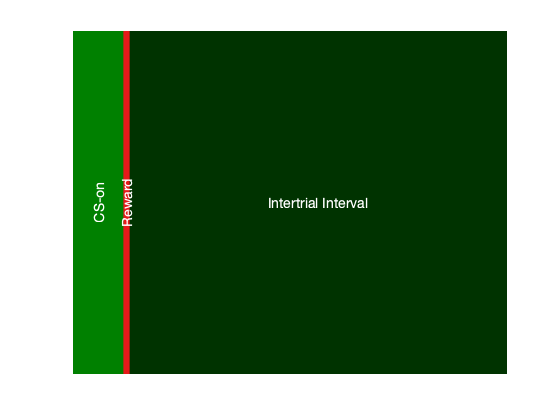

midpoint_timestep_offsets = (end_timesteps - start_timesteps) ./ 2.0;
midpoint_timesteps = start_timesteps + midpoint_timestep_offsets;


y_offset = (state_stack_dim.Lim(2) - state_stack_dim.Lim(1)) / 2;
y_midpoint = min(state_stack_dim.Lim) + y_offset;
y_midpoints = repelem(y_midpoint, numBlocks);

h = text(seconds(midpoint_timesteps), y_midpoints, titles, ...
    'VerticalAlignment','middle','HorizontalAlignment','center',...
    'FontSize',14,'Color','white');


for s_idx = 1:numBlocks
%     h = text(X(:,10),X(:,i),labels,'VerticalAlignment','top','HorizontalAlignment','right');
%     h = annotation('textbox', [0.5, 0.2, 0.1, 0.1], 'String', titles{s_idx});
%     
    
    set(h(s_idx), 'Rotation', title_options.Rotations(s_idx));
end

## Draw "Wishbone-like" Length Indicator

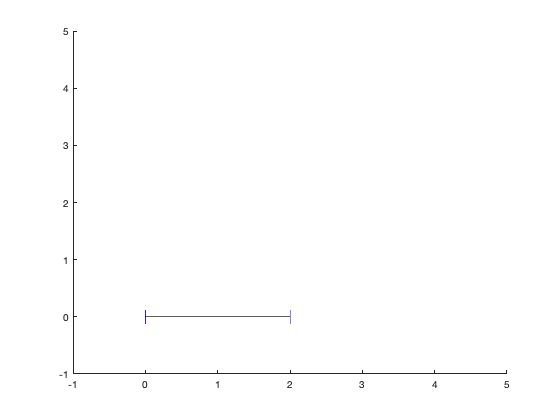

figure
clf

centerPoint = [0 0];
plottingOptions.majorAxisStartEnd = [0 2];
[plotHandle] = fnPlotHelper_DrawLengthIndicator(centerPoint, plottingOptions);

xlim([-1 5]);
ylim([-1 5]);